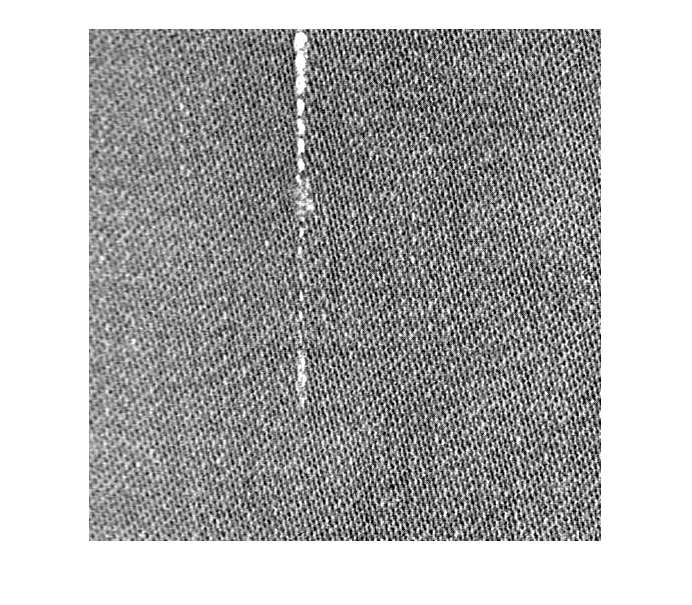

% Martedi 03 Novembre 2020 - Mercoledi 04 Novembre 2020
% Corso di Elaborazione dei Segnali e Immagini
% Docente: Ilaria Boscolo Galazzo 
% Docente Coordinatore: Marco Cristani
% Tutor lab: Christian Joppi 
% LAB2 - parte 2

clear all
close all
clc

%Esercizio 1 - Cross-correlazione 2D normalizzata per trovare difetti su tessuti
B= rgb2gray(imread('i16.jpg'));
[R,C]=size(B);

%Aumento contrasto con imadjust con stretchlim che imposta automaticamente
%la soglia minima del contrasto
A = imadjust(B,stretchlim(B),[]);
figure;
imshow(A);


%Ricerca dimensione pattern ideale
i = 0;
j = 1;
inizio = 1;
fine = 8;
times =  linspace(inizio,fine,8); 

%Ricerca dei massimi  di correlazione con funzione graycoprops
offsets0 = [zeros(40,1) (1:40)'];
glcm = graycomatrix(A, 'offset', offsets0);
stats = graycoprops(glcm,'Contrast Correlation');
figure, plot([stats.Correlation]);
title('Texture Correlation as a function of offset');
xlabel('Horizontal Offset')
ylabel('Correlation')    

%Ricerca dei massimi
Massimi = findpeaks(stats.Correlation);
if Massimi < 3
    %Se i massimi sono meno di 3
    Massimi = Massimi(length(Massimi));
else
    %Pulizia dei massimi non rilevanti
    Massimi = Massimi(3:length(Massimi));
end

%Massimi rilevanti ordinati in ordine decrescente
Massimi = sort(Massimi, 'descend');

%Prendo dal primo posto dell'array il valore corrispondente alla dimensione
%ottimale da utilizzare come pattern
maxValue = Massimi(1);

%Prendo la dimensione ottimale del pattern
patternDimension = find(stats.Correlation == maxValue);

% Definisco i pattern con la dim ottimale ricavata sopra
%Facciamo 8 pattern , 2 per ogni angolo
pattern1 = A(1 : patternDimension, 1 : patternDimension);                   %Alto a sinistra
pattern2 = A(R - patternDimension : R - 1, C - patternDimension : C - 1);     %Basso a destra
pattern3 = A(R - patternDimension : R - 1, 1 : patternDimension);               %Basso a sinistra
pattern4 = A(1 : patternDimension, C - patternDimension : C - 1);           %Alto a destra
pattern5 = A(2 : patternDimension + 1, 2 : patternDimension + 1);
pattern6 = A(R - patternDimension - 1 : R - 2, C - patternDimension - 1 : C - 2 );
pattern7 = A(R - patternDimension - 1 : R - 2, 2 : patternDimension + 1 );
pattern8 = A(2 : patternDimension + 1, C - patternDimension - 1 : C - 2);
pattern9 = A(3 : patternDimension + 2, 3 : patternDimension + 2);
pattern10= A(3 : patternDimension + 2, C - patternDimension - 2 : C - 3);

% Calcolo la xcorr-2D (normalizzata). Size = N+M-1
c1 = normxcorr2(pattern1,A); 
c2 = normxcorr2(pattern2,A);
c3 = normxcorr2(pattern3,A);
c4 = normxcorr2(pattern4,A);
c5 = normxcorr2(pattern5,A);
c6 = normxcorr2(pattern6,A);
c7 = normxcorr2(pattern7,A);
c8 = normxcorr2(pattern8,A);
c9 = normxcorr2(pattern9,A);
c10= normxcorr2(pattern10,A);

% From MATLAB Help:
% C = normxcorr2(TEMPLATE,A) computes the normalized cross-correlation of
%     matrices TEMPLATE and A. The matrix A must be larger than the matrix
%     TEMPLATE for the normalization to be meaningful. The values of TEMPLATE
%     cannot all be the same. The resulting matrix C contains correlation
%     coefficients and its values may range from -1.0 to 1.0.

c = (c1 + c2 + c3 + c4 + c5 + c6 + c7 + c8 + c9 + c10) / 10; % calcolo media (537x537)
display(mean(abs(c),'all'));

    0.0766



%Prova parametrizzazione raggio disk strel

if mean(abs(c),'all') < 0.07
    sizeofdisk = 1;
else
    sizeofdisk = 2;
end

[altezza, larghezza] = size(c);
scarto = (altezza-500)/2;
scarto = cast(scarto,'int32');
if rem(altezza,2) ~= 0
    c = c(scarto:(end-scarto),scarto:(end-scarto));
else
    c = c(scarto:(end-(scarto+1)),scarto:(end-(scarto+1)));
end

figure, surf(abs(c)), shading flat
figure, imagesc(abs(c)), colorbar
c = abs(c);
display(c);

c =     0.0021    0.0086    0.0012    0.0194    0.0310    0.0200    0.0021    0.0126    0.0022    0.0148    0.0142    0.0052    0.0202    0.0073    0.0215    0.0378    0.0247    0.0012    0.0090    0.0111    0.0367    0.0376    0.0111    0.0114    0.0035    0.0237    0.0366    0.0186    0.0110    0.0181    0.0069    0.0347    0.0341    0.0080    0.0101    0.0033    0.0332    0.0426    0.0174    0.0145    0.0174    0.0109    0.0369    0.0318    0.0029    0.0131    0.0066    0.0417    0.0506    0.0207
    0.0053    0.0089    0.0077    0.0108    0.0274    0.0236    0.0037    0.0109    0.0053    0.0118    0.0149    0.0033    0.0231    0.0168    0.0108    0.0329    0.0263    0.0011    0.0112    0.0049    0.0317    0.0354    0.0066    0.0246    0.0226    0.0090    0.0339    0.0245    0.0076    0.0240    0.0040    0.0288    0.0360    0.0088    0.0204    0.0161    0.0181    0.0423    0.0279    0.0069    0.0216    0.0005    0.0301    0.0342    0.0070    0.0187    0.0103    0.0243    0.0450    0


% Graythreshold
lv = graythresh(c);
maskt = c > (lv);
display(size(maskt));

   500   500



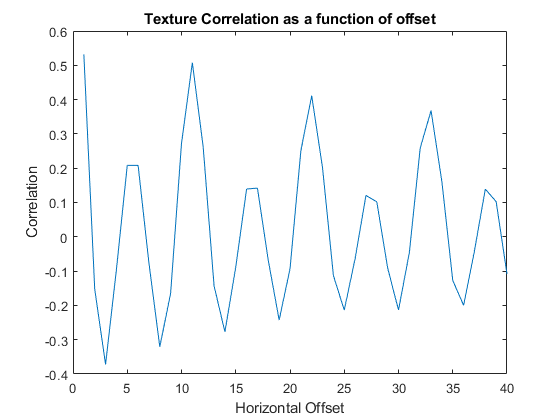

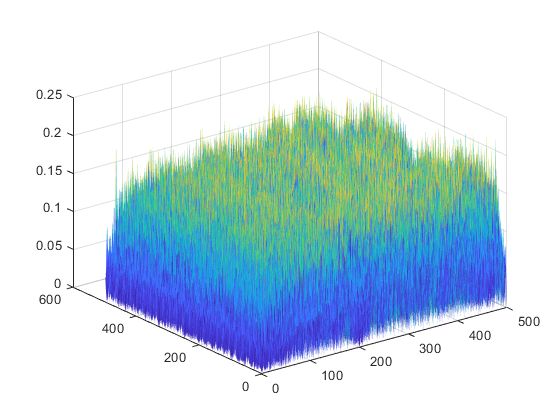

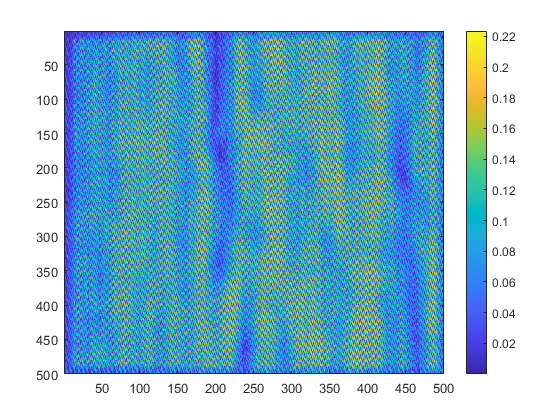

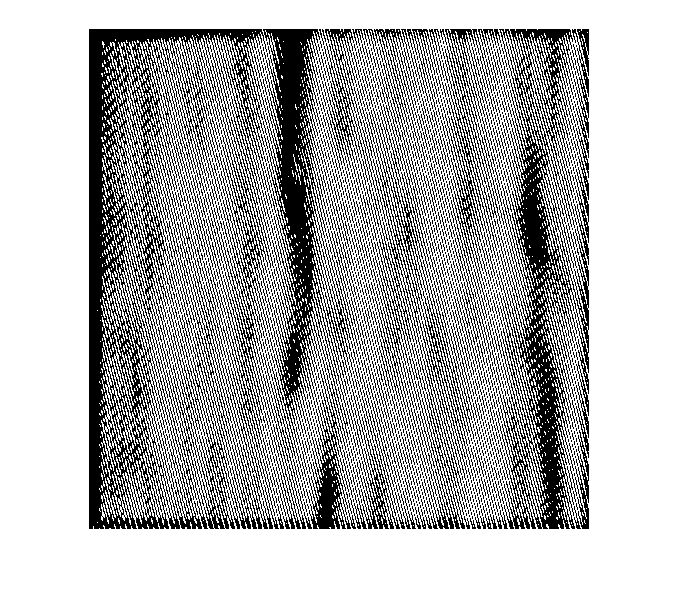

figure; 
imshow(maskt);

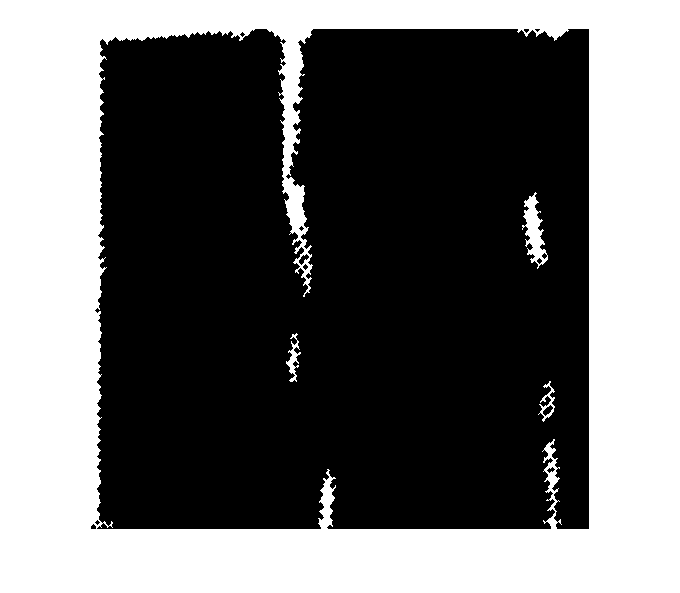


se3 = strel("disk", sizeofdisk);
maskt = imdilate(maskt , se3);
maskt = imcomplement(maskt);
CC = bwconncomp(maskt);         %Componenti iù grandi connessi
maskt = bwareafilt(maskt,CC.Connectivity,'largest');
imshow(maskt);

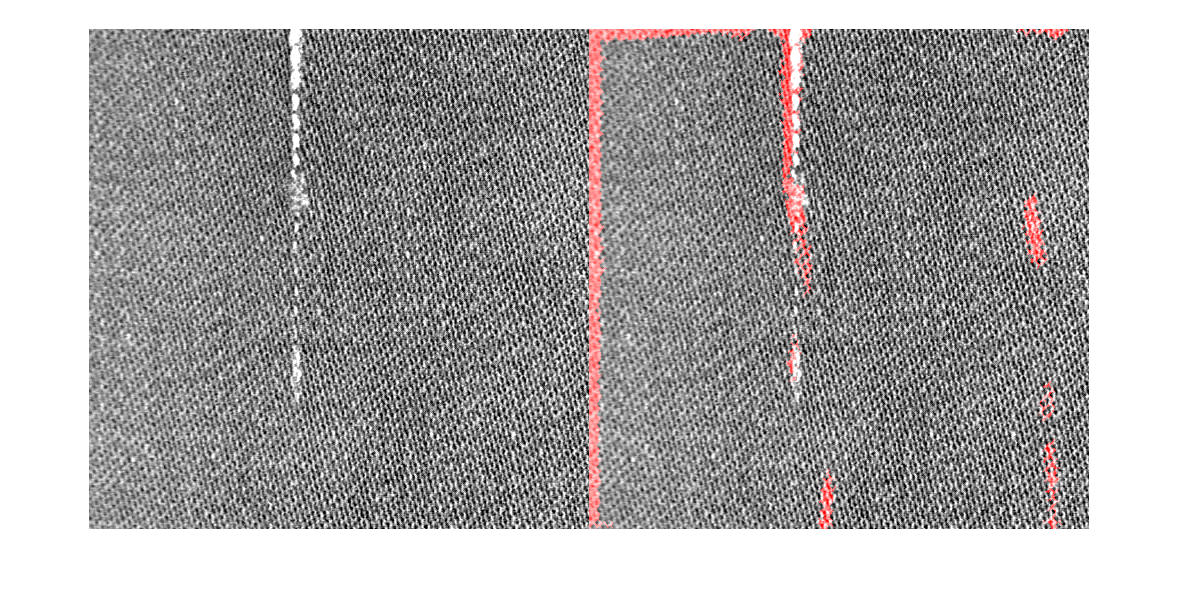

A=A(6:end-7,6:end-7);           % Passo da 512x512 a 500x500
A1 = A;
A1(maskt)=255;

Af=cat(3,A1,A,A);
figure;
imshowpair(A,Af,'montage')